# Playing with points

Geometrical points are entities characterized by their position in a given refernece frame. In Anakin, the class `point` allows creating them. Points inherit their properties and methods from the `vector` class, and this example focuses on the unique aspects of the `point` class.

Start by importing the Anakin framework into Matlab. Be sure to include Anakin's base directory before you run this line:

import anakin.*

## Object creation

The default geometric point is the canonical origin:

O = point % default call

O = Geometric point with canonical position:
     0
     0
     0


Points can be created by passing their position vector or its canonical coordinates:

ra = vector([1;2;3])

ra = Vector with canonical components:
     1
     2
     3


A = point(ra) % as a vector

A = Geometric point with canonical position:
     1
     2
     3


A = point([4;5;6]) % as a column array

A = Geometric point with canonical position:
     4
     5
     6


A = point([7,8,9]) % as a row array

A = Geometric point with canonical position:
     7
     8
     9



A = point(1,2,3) % canonical coordinates

A = Geometric point with canonical position:
     1
     2
     3


The components that define the point can be given in another reference frame. Internally, the point object stores only its coordinates in the canonical reference frame:

O1 = point([1;2;3]);
B1 = basis([1;0;0],[0;cos(pi/6);sin(pi/6)],[0;-sin(pi/6);cos(pi/6)]);
S1 = frame(O1,B1);

A = point(1,1,1,S1)

A = Geometric point with canonical position:
    2.0000
    2.3660
    4.3660


For convenience, any object of point class or a subclass can be passed as input. The result is converted to class point:

P = particle; % a particle object, subclass of point
A = point(P); % converted to point

## Basic functionality

To obtain the position vector of a point with respect to the origin of a reference frame, use method `pos:`

O1 = point([1;2;3]); 
S1 = frame(O1);
A = point(1,1,1,S1);

A.pos

ans = Vector with canonical components:
     2
     3
     4


A.pos(S1)

ans = Vector with canonical components:
     1
     1
     1


Coordinates can be extracted similarly:

A.coordinates(S1)

ans =      1
     1
     1


A.x(S1)

ans = 1

A.y(S1)

ans = 1

A.z(S1)

ans = 1

One can displace the position vector of a point with another vector:

A = point(1,2,3);
v = vector([2;2;2]);

A.displace(v)

ans = Geometric point with canonical position:
     3
     4
     5


There are several operators and methods in the `vector` class that are meaningless for a geometric point and have thus been removed: `+`, `-`, `.*`, `*`, `./`, `/`, `.\`, `\`, `dot`, norm, `cross`, `dir`, `magnitude`, `components`, `dt`, `isunitary`, `isperpendicular`, `isparallel`. Any attempt to use them will raise an error:

try
    A+A % This is an error
catch ME
    disp(ME.message)
end

This usage of point is not permitted


A numeric point can be plotted using `plot`:

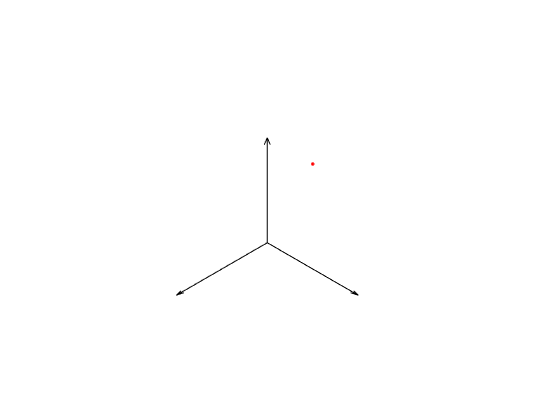

ax = axes('DataAspectRatio',[1,1,1]);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';
view([1,1,1]);

S1.plot; % plot the frame first

A = point([1;1.5;2],S1);
A.plot('color','r'); % pass quiver3 plotting arguments to change color, style, etc.

## Symbolic points

Points with symbolic coordinates have additional functionality (running this requires the Symbolic Math Toolbox installed):

syms t xi(t) eta(t) zeta(t) phi(t); % declare symbolic variables
assume([in(t, 'real'), in(xi(t), 'real'), in(eta(t), 'real'), in(zeta(t), 'real'), in(phi(t), 'real')]); 

A = point(xi,eta,zeta) % a symbolic point

A = Geometric point with canonical position:
   xi(t)
  eta(t)
 zeta(t)
 

One may compute the velocity and acceleration of a point with respect to a given reference frame. If no reference frame is provided, the canonical one is assumed:

A.vel 

ans = Vector with canonical components:
   diff(xi(t), t)
  diff(eta(t), t)
 diff(zeta(t), t)
 

A.accel

ans = Vector with canonical components:
   diff(xi(t), t, t)
  diff(eta(t), t, t)
 diff(zeta(t), t, t)
 


O = point(xi^2,0,0);
B1 = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);
S1 = frame(O,B1);

A.vel(S1) 

ans = Vector with canonical components:
             -(2*xi(t) - 1)*diff(xi(t), t)
 zeta(t)*diff(phi(t), t) + diff(eta(t), t)
 diff(zeta(t), t) - eta(t)*diff(phi(t), t)
 

A.accel(S1)

ans = Vector with canonical components:
                                                          - 2*diff(xi(t), t)^2 - (2*xi(t) - 1)*diff(xi(t), t, t)
 zeta(t)*diff(phi(t), t, t) - eta(t)*diff(phi(t), t)^2 + 2*diff(phi(t), t)*diff(zeta(t), t) + diff(eta(t), t, t)
 diff(zeta(t), t, t) - zeta(t)*diff(phi(t), t)^2 - 2*diff(eta(t), t)*diff(phi(t), t) - eta(t)*diff(phi(t), t, t)
 